% orbit - Program to compute the orbit of a comet.
clear all;  

%* Set initial position and velocity of the comet.
r0 = 1;
v0 = pi;
r = [r0 0];  v = [0 v0];
state = [ r(1) r(2) v(1) v(2) ];   % Used by R-K routines

%* Set physical parameters (mass, G*M)
GM = 4*pi^2;      % Grav. const. * Mass of Sun (au^3/yr^2)
mass = 1.;        % Mass of comet 
adaptErr = 1.e-3; % Error parameter used by adaptive Runge-Kutta
time = 0;

% find theoretical values for error in distance
% square of angular momentum
L2 = (r0 * v0) ^ 2;
% get energy from initial conditions
m = mass;
KE = m * (v0 ^ 2) / 2;
PE = - GM * m / r0;
E = KE + PE;
ecc = sqrt(1 + 2*E*L2/((GM)^2 * m^3))

ecc = 0.7500

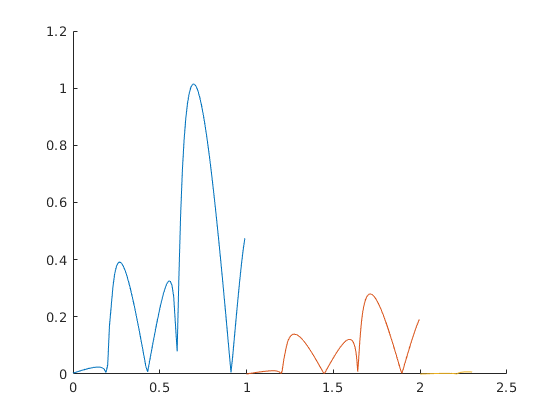


%* Loop over desired number of steps using specified
%  numerical method.
nStep = [100, 200, 300];
tau = [0.01, 0.005, 0.001];
NumericalMethod = 2;
hold on
for i = 1:length(tau)
    % reset values
    r = [r0, 0];
    v = [0, v0];
    state = [r(1) r(2) v(1) v(2)];
    thplot = [];
    rplot = [];
    tplot = [];
    for iStep=1:nStep(i)
        %* Record position and energy for plotting.
        rplot(iStep) = norm(r);           % Record position for polar plot
        thplot(iStep) = atan2(r(2),r(1));
        tplot(iStep) = time;
        kinetic(iStep) = .5*mass*norm(v)^2;   % Record energies
        potential(iStep) = - GM*mass/norm(r);
        %* Calculate new position and velocity using desired method.
        if( NumericalMethod == 1 )
            accel = -GM*r/norm(r)^3;   
            r = r + tau(i)*v;             % Euler step
            v = v + tau(i)*accel; 
            time = time + tau(i);   
        elseif( NumericalMethod == 2 )
            accel = -GM*r/norm(r)^3;   
            v = v + tau(i)*accel; 
            r = r + tau(i)*v;             % Euler-Cromer step
            time = time + tau(i);     
        elseif( NumericalMethod == 3 )
            state = rk4(state,time,tau(i),'gravrk',GM);
            r = [state(1) state(2)];   % 4th order Runge-Kutta
            v = [state(3) state(4)];
            time = time + tau(i);   
        else
            [state time tau(i)] = rka(state,time,tau(i),adaptErr,'gravrk',GM);
            r = [state(1) state(2)];   % Adaptive Runge-Kutta
            v = [state(3) state(4)];
        end
    end
    % find semi-major axis
    rmax = max(abs(rplot));
    a = rmax / (1 + ecc);
    % theoretical radial distance for value of tau
    r = @(th) (a * (1 - ecc^2)) / (1 - ecc*cos(th));
    r_theo = arrayfun(r, thplot);
    % find error and plot vs angle
    err = abs(rplot - r_theo) ./ r_theo;
    semilogy(tplot, err)
end
hold off